**EE 150**

**Signals and Systems**

** Lab 5 Sampling and Reconstruction**

Date Performed: 2023/05/04

Class Id: Thurs 107

Name & ID: huanglei 2021533161 renhui 2021533089

1 Create $\textrm{signal}3=\sin \left(1\ldotp 2\pi t\right)*\;\cos \left(1\ldotp 6\pi t\right)+0\ldotp 5*\cos \left(2\pi t\right)$

1.1 Plot the original signal and its spectrum (amplitude-frequency only). Record the highest frequency of the signal as **fb** and display it.

1.2 Sample signal3 at 1.5 times of **fb** and then reconstruct it. Plot the sampled signal, the spectrum of the sampled signal and the reconstructed signal.

1.3 Sample signal3 at 3 times of **fb** and then reconstruct it. Plot the sampled signal, the spectrum of the sampled signal and the reconstructed signal.

Organize all the plot in a  3*3 plot as following.

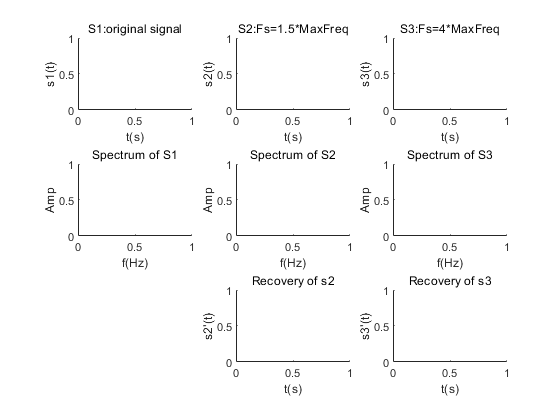

clear; clf;
N = 300;
Fs = 50;
df = Fs/N;
dt = 1/Fs;
t = (0:N-1)/Fs;
%original signal
ft = sin(1.2*pi.*t) .* cos(1.6 * pi .* t) + 0.5 * cos(2*pi.*t);
T = 5;
subplot(3,3,1);
plot(t,ft); xlim([0,6]); ylim([-1.5,1.5]); title("oringal signal");  xlabel("t(s)"); ylabel("f(t)");
y_amp = abs(fftshift(fft(ft))) / N;
f = ((-N/2):(N/2-1)) * df;
subplot(3,3,4);
plot(f,y_amp);  title("spectrum of s1"); xlabel("f(Hz)"); ylabel("Amp");xlim([-2.5,2.5]); ylim([0,0.35]);
fb = 1.4 % By observe and analysis, fb = 1.4.

fb = 1.4000

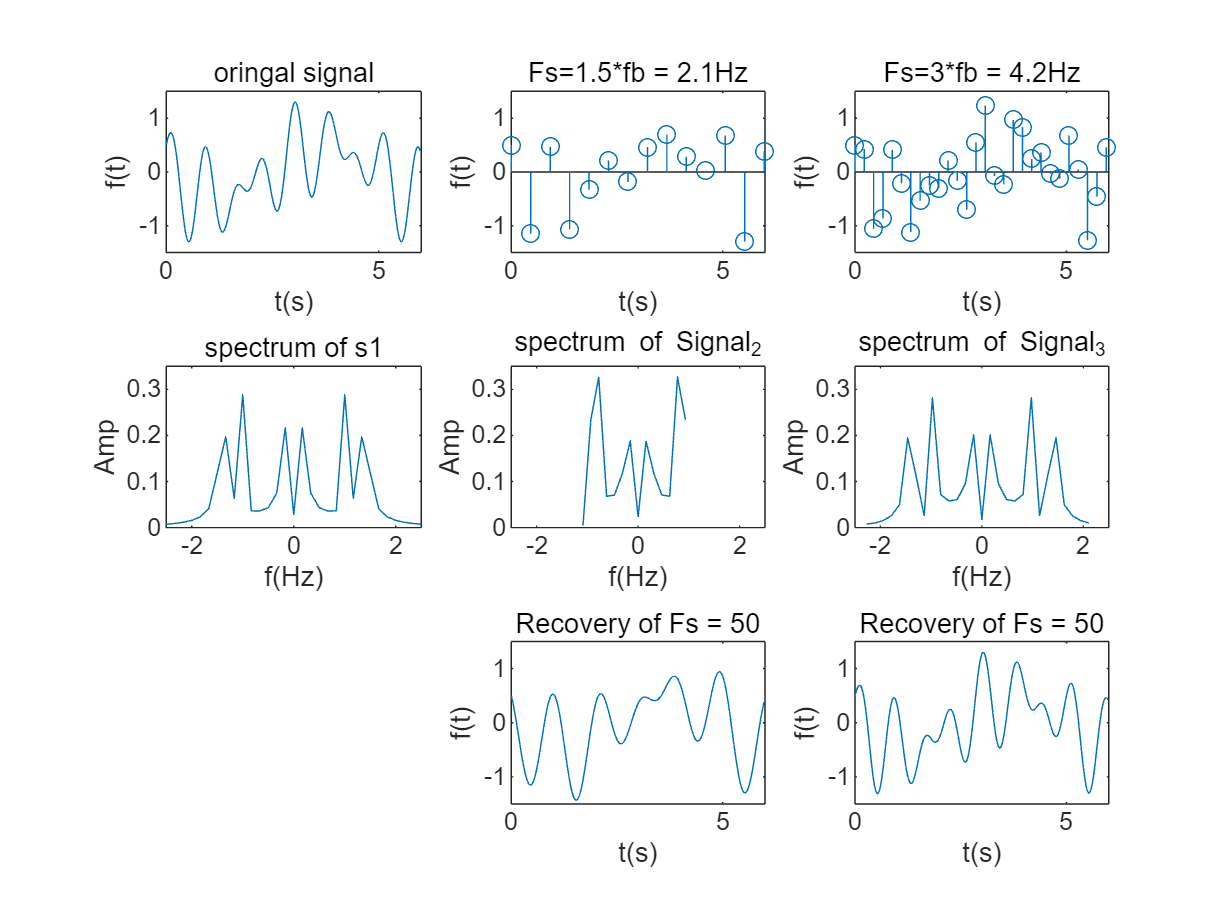

Fs2 = [1.5*fb,3*fb];
ds = 1./Fs2;
sample_interval = floor(ds/dt);
for i = 1:length(sample_interval)
    %sample signal
    f_sample = ft(1:sample_interval(i):end);
    t_sample = t(1:sample_interval(i):end);
    Ts = sample_interval(i)*dt;
    sigLen = length(f_sample);
    %do fourier transform with fft
    N = sigLen;
    fs = 1/Ts;
    df = fs/N;
    F = fftshift(abs(fft(f_sample)))/sigLen;
    f = (-N/2:N/2-1)*df;
    
    % plot time domain signal
    subplot(3,3,i+1);
    stem(t_sample,f_sample); xlabel('t(s)'); ylabel('f(t)');
    title("Fs=" + num2str(Fs2(i) / fb) + "*fb = " + num2str(Fs2(i)) + 'Hz'); xlim([0,6]); ylim([-1.5,1.5]);
    % plot freq domain signal
    subplot(3,3,i+4);
    plot(f,F); xlabel('f(Hz)'); ylabel('Amp'); xlim([-2.5,2.5]); ylim([0,0.35]);
    title(["spectrum of Signal_" + num2str(i+1)])
    % plot reconstruct
    subplot(3,3,i+7);
    sig_recon=zeros(length(t),1);
    for k=1:length(t)
        for n=1:length(f_sample)
            sig_recon(k)=sig_recon(k)+f_sample(n)*sinc(((k-1)*dt-(n-1)*Ts)/Ts);
        end
    end
    plot(t,sig_recon); title("Recovery of Fs = " + num2str(Fs)); xlabel("t(s)"); ylabel("f(t)"); xlim([0,6]); ylim([-1.5,1.5]);
end

2 Load ***Lab5_music.mat***. It's a piece of music downed in noise. 

2.1 Plot the original signal in both time domain and frequency domain (amplitude-frequency only) in a 1*2 subplot.

2.2 Observe the spectrum of the original signal to find out the signal bandwidth **fb**. Take 2***fb** as the sampling frequency, then sample the original signal. Plot the the sampled signal in both time domain and frequency domain in a 1*2 subplot. Play and listen to it.

2.3  Use an appropriate anti-aliasing filter to filter the original signal. Plot the filtered signal in both time domain and frequency domain in a 1*2 subplot.

2.4  Take 2***fb** as the sampling frequency, sample the filtered signal, then draw the sampled signal in both time domain and frequency domain in a 1*2 subplot. Play and listen to it.

Tips:

Load ***Lab5_music.mat*** with function **load("Lab5_music.mat"** **) **to get the original signal. 

Use** figure** to create a new canva for each 2.x.

clear; clf;
load("Lab5_music.mat");

错误使用 load
找不到文件或目录 'Lab5_music.mat'。

signal=signal';

% 2.1
dt=1/Fs;
N=length(signal);
df=Fs/N;
t=[0:N-1]*dt;
f=[-N/2:N/2-1]*df;
subplot(1,2,1);
plot(t,signal); xlabel('t(s)'); ylabel('s(t)'); title('origin signal');
X=fft(signal);
Y=abs(X)*dt;
Yshift=fftshift(Y);
subplot(1,2,2);
plot(f,Yshift); xlabel('f(Hz)'); ylabel('Amp');
title('frequency domain');


% 2.2
figure;
fb=2000;
fs=2*fb;
ds=1/fs;
sample_interval=floor(ds/dt);
t_sample=t(1:sample_interval:end);
sig_sample=signal(1:sample_interval:end);
subplot(1,2,1); stem(t_sample,sig_sample);
xlabel('t(s)'); ylabel('signal_1[t]'); title('Sampled Signal');

N=length(sig_sample);
df=fs/N;
f=[-N/2:N/2-1]*df;
X=fft(sig_sample);
Y=abs(X)*sample_interval*dt;
Yshift=fftshift(Y);
subplot(1,2,2);
plot(f,Yshift); xlabel('f(Hz)'); ylabel('Amp');
title("spectrum of signal_1 (sampled)"); sound(sig_sample,fs); pause(length(sig_sample) / fs);

% 2.3 
figure;
dt=1/Fs;
N=length(signal);
df=Fs/N;
t=[0:N-1]*dt;
f=(-N/2:N/2-1)*df;
fc = 2000+50;
[b,a] = butter(16,fc/(Fs/2));

filtered_signal = filter(b,a,signal);
subplot(1,2,1);
plot(t,filtered_signal); xlabel('t(s)'); ylabel('signal_2(t)'); title('filtered signal time domain');
X=fft(filtered_signal);
Y = abs(X)*dt;
Yshift = fftshift(Y);
subplot(1,2,2);
plot(f,Yshift); xlabel('f(Hz)'); ylabel('Amp');
title('filtered Signal frequency domain');

% 2.4
figure;
fb=2000;
fs=2*fb;
ds=1/fs;
sample_interval=floor(ds/dt);
t_sample=t(1:sample_interval:end);
y_sample=filtered_signal(1:sample_interval:end);
subplot(1,2,1); stem(t_sample,y_sample);
xlabel('t(s)'); ylabel('s1(t)'); title('Sampled Filtered Signal');

N=length(y_sample);
df=fs/N;d
f=[-N/2:N/2-1]*df;
X=fft(y_sample);
Y=abs(X)*sample_interval*dt;
Yshift=fftshift(Y);
subplot(1,2,2);
plot(f,Yshift); xlabel('f(Hz)'); ylabel('Amp');
title('Sampled Filtered Signal frequency domain'); sound(y_sample,fs); pause(length(y_sample)/fs);